## Ligevægt af bilen

Den ydre belastning består af:

- Køretøjets egenvægt, $mg$, $m = 150 kg$. 

- Luftmodstand, $F_L = \frac{1}{2} \rho_{luft} c A v^2$ på grund af køretøjets luftmodstand, hvor, $v = 70 km/h$, $A = 0.6 m^2$, $\rho_{luft} = 1.21 kg/m^3$, $c = 0.25$.  

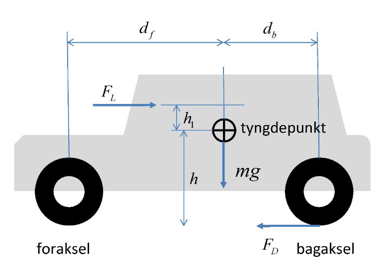


$$d_f = 800 mm, \quad h = 20 cm$$


$d_b = 200 mm, \quad h_1 = 30 cm$.

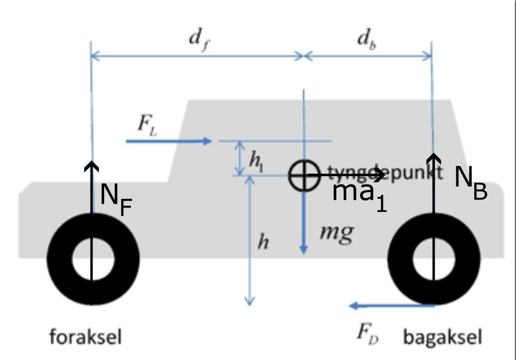

Baseret på ovenstående frit-legeme diagram kan vi lave en kraft-ligevægt i x-retningen hvorledes vi får:


$$F_D - F_L - m a_1 = 0 \iff F_D = F_L + m a_1$$


En moment ligevægt fra forakslen giver:


$$N_B (d_f + d_b) - mg d_f - F_L (h + h_1) - ma_1 h = 0 \iff N_B = \frac{mg d_f + F_L (h + h_1) + ma_1 h}{d_f + d_b}$$


clear; close all; clc;

%Definitioner af givne størrelser i SI
g = 9.81; %m/s^2
m = 150;  %kg
v = 70/3.6; %m/s
A = 0.6; %m^2
rho = 1.21; %kg/m^3
c = 0.25;
d_f = 0.8; %m
d_b = 0.2; %m
h = 0.2; %m
h_1 = 0.3; %m
a_1 = 5; %m/s^2

%Luftmodstand
F_L = 0.5 * rho *  c * A * v^2;

%"Drivkraften" mellem dækket og vejen
F_D = F_L + m * a_1;

%Normalkraften på bagakslen
N_B = (m * g * d_f + F_L * (h + h_1) + m * a_1 * h)/(d_f + d_b);

%Normalkraft på foraksel (ligevægt i y-aksen)
N_F = m * g - N_B;

%Gem resultater i en struct
bil = struct();
bil.F_L = F_L;
bil.F_D = F_D;
bil.N_B = N_B;
bil.N_F = N_F;

save('bil_ligevaegt.mat','bil');

%Output resultater
fprintf('\n=== Ligevægt for bil ===\n');


=== Ligevægt for bil ===


fprintf('F_L    = %.2f N\n', bil.F_L);

F_L    = 34.31 N


fprintf('F_D    = %.2f N\n', bil.F_D);

F_D    = 784.31 N


fprintf('N_B    = %.2f N\n', bil.N_B);

N_B    = 1344.36 N


fprintf('N_F    = %.2f N\n', bil.N_F);

N_F    = 127.14 N
